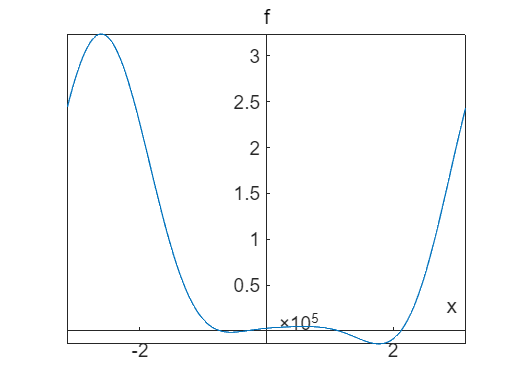


ezplot(@f,[-pi,pi]);hold on%画出函数图像
ax=gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';%画出原点处坐标轴
axis([-inf inf -inf inf]);%坐标轴范围随函数值域调整

t1=fzero(@f,2)

t1 =    2.115909014086458


t2=fzero(@f,1)

t2 =    1.143685517821374


t3=fzero(@f,0)

t3 =   -0.331005184283869


t4=fzero(@f,-1)%根据函数图像，求解出四个位置根的数值解

t4 =   -0.720849204460390


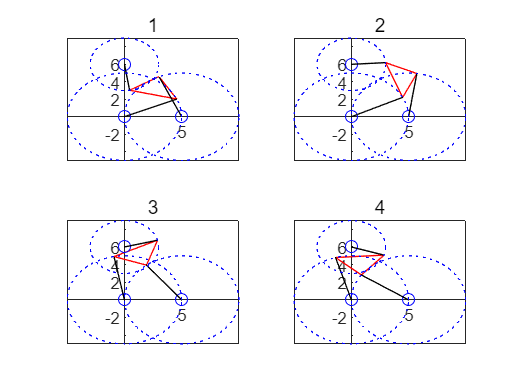

theta=[t1,t2,t3,t4];%解向量
L1=3;
L2=3*sqrt(2);
L3=3;
gamma=pi/4;
p1=5;
p2=5;
p3=3;
x1=5;
x2=0;
y2=6;%参数
A2=L3.*cos(theta)-x1;
B2=L3.*sin(theta);
A3=L2.*(cos(theta).*cos(gamma)-sin(theta).*sin(gamma))-x2;
B3=L2.*(cos(theta).*sin(gamma)+sin(theta).*cos(gamma))-y2;
D=2.*(A2.*B3-B2.*A3);
M1=p2.^2-p1.^2-A2.^2-B2.^2;
M2=p3.^2-p1.^2-A3.^2-B3.^2;
N1=B3.*M1-B2.*M2;
N2=-A3.*M1+A2.*M2;%计算相关式子
u1=N1./D;
v1=N2./D;%计算第一个点横纵坐标
u2=u1+L3.*cos(theta);
v2=v1+L3.*sin(theta);%计算第二个点横纵坐标
u3=L2.*cos(theta+gamma)+u1;
v3=L2.*sin(theta+gamma)+v1;%计算第三个点横纵坐标
t=linspace(0,2*pi);%为画圆设置参数
figure%创建图窗窗口
%画出4种位置姿态图
for i=1:4
    subplot(2,2,i);%在第i个窗口
    plot([u1(i) u2(i) u3(i) u1(i)],[v1(i) v2(i) v3(i) v1(i)],'r');hold on%画出三角形平台
    plot([0 x1 x2],[0 0 y2],'bo');hold on%描出锚点
    plot([0 u1(i) 0],[0 v1(i) 0],'k');hold on
    plot([x1 u2(i) x1],[0 v2(i) 0],'k');hold on
    plot([x2 u3(i) x2],[y2 v3(i) y2],'k');hold on%画出支杆
    plot((p1.*cos(t)),(p1*sin(t)),'b:');hold on
    plot((p2.*cos(t)+x1),(p2*sin(t)),'b:');hold on
    plot((p3.*cos(t)+x2),(p3*sin(t)+y2),'b:')%画出关节运动圆，以检查结果
    ax=gca;
    ax.XAxisLocation = 'origin';
    ax.YAxisLocation = 'origin';
    axis([-inf inf -inf inf]);%画出原点处坐标轴
    title(i)%名称
end

Eb1=abs(f(t1))%零点的后向误差

Eb1 =      0


Eb2=abs(f(t2))

Eb2 =      5.456968210637569e-12


Eb3=abs(f(t3))

Eb3 =      0


Eb4=abs(f(t4))

Eb4 =      0


Ep1=max(abs([(norm([u1(1),v1(1)])-p1),(norm([u2(1)-x1,v2(1)])-p2),(norm([u3(1)-x2,v3(1)-y2])-p3)]))

Ep1 =      8.881784197001252e-16


Ep2=max(abs([(norm([u1(2),v1(2)])-p1),(norm([u2(2)-x1,v2(2)])-p2),(norm([u3(2)-x2,v3(2)-y2])-p3)]))

Ep2 =      8.881784197001252e-16


Ep3=max(abs([(norm([u1(3),v1(3)])-p1),(norm([u2(3)-x1,v2(3)])-p2),(norm([u3(3)-x2,v3(3)-y2])-p3)]))

Ep3 =      0


Ep4=max(abs([(norm([u1(4),v1(4)])-p1),(norm([u2(4)-x1,v2(4)])-p2),(norm([u3(4)-x2,v3(4)-y2])-p3)]))

Ep4 =      4.440892098500626e-16


%关于支杆长度的前向误差

function out=f(theta)%为了求得theta,构造f(theta)=0所需f
format long;
L1=3;
L2=3*sqrt(2);
L3=3;
gamma=pi/4;
p1=5;
p2=5;
p3=3;
x1=5;
x2=0;
y2=6;%更改所需参数
A2=L3.*cos(theta)-x1;
B2=L3.*sin(theta);
A3=L2.*(cos(theta).*cos(gamma)-sin(theta).*sin(gamma))-x2;
B3=L2.*(cos(theta).*sin(gamma)+sin(theta).*cos(gamma))-y2;
D=2.*(A2.*B3-B2.*A3);
M1=p2.^2-p1.^2-A2.^2-B2.^2;
M2=p3.^2-p1.^2-A3.^2-B3.^2;
N1=B3.*M1-B2.*M2;
N2=-A3.*M1+A2.*M2;%按照上述数学公式推导，计算所需关系式
out=N1.^2+N2.^2-p1.^2*D.^2;%输出函数
end